# Actividad de clase: Cubo

Mateo Minghi - A01711231

La Fuerza de Lorentz, en su forma incompleta, habla de la fuerza producida por un campo magnético sobre una partícula:


$$\vec{F} =Q\;\vec{v} x\;\vec{B}$$


Donde $\vec{F}$ es la Fuerza (vectorial), Q es la carga de la partícula, $\vec{v}$es la velocidad (vectorial), y $\vec{B}$ es el campo magnético. Por su parte, $\vec{B}$ está denotado por la expresión del campo magnético considerando la permeabilidad en el vacío:


$$\vec{B} =\frac{I\mu_0 }{2\pi \rho }\hat{a} \o$$


Para este ejercicio, todas las partículas s enecuentran dentro de un cubo. 

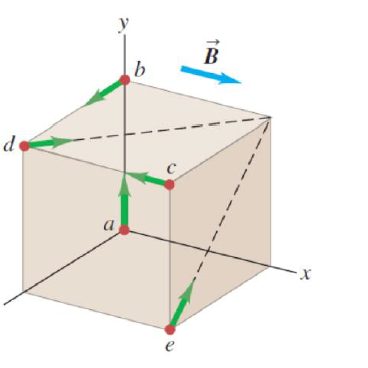

Se establece el número de cargas dentro del cubo:

num_cargas = input('Ingrese el número de cargas dentro del cubo: ');

En este programa flexible y elegante como le querría el Dr. Momox, la idea es trabajar con variables simbólicas. Como el usuario ingresa datos de tipo "string", se convierten a simbólicas:

syms q_sym v_x_sym v_y_sym v_z_sym Bx_sym By_sym Bz_sym real

Se le piden al usuario los valores de la carga (asumiendo que todas las cargas tienen el msimo valor), así como las componentes del campo magnético (en este caso, el campo magnético se encuentra sobre el eje x):

q = input('Ingrese el valor de la carga Q: ');
Bx = input('Ingrese la componente x del campo magnético unitario Bx: ');
By = input('Ingrese la componente y del campo magnético unitario By: ');
Bz = input('Ingrese la componente z del campo magnético unitario Bz: ');

Como $\vec{B}$ es un vector, se guardan sus componentes:

B_vector = [Bx_sym, By_sym, Bz_sym];

La fuerza es vectorial también. Se establece como un vector lleno de ceros que será llenado:

F = sym(zeros(num_cargas, 3));

De manera teórica, lo que define si una carga experimenta fuerza por el campo magnético es el producto cruz ($\vec{v} x\;\vec{B}$), así como la dirección de la fuerza resultante que actúa sobre la carga. Si el resultado fuera cero, no habría fuerza:

for i = 1:num_cargas
fprintf('Ingrese las componentes de la velocidad para la carga %d:\n', i);
v_x = input('Componente x de la velocidad v_x: ');
v_y = input('Componente y de la velocidad v_y: ');
v_z = input('Componente z de la velocidad v_z: ');

%Velocidad de la carga
v_vector = [v_x_sym, v_y_sym, v_z_sym];

%fuerza magnética
F(i, :) = q_sym * cross(v_vector, B_vector);
% Sustituir los valores ingresados
F_val = subs(F(i, :), {q_sym, v_x_sym, v_y_sym, v_z_sym, Bx_sym, By_sym, Bz_sym}, ...
{q, v_x, v_y, v_z, Bx, By, Bz});

% Mostrar la fuerza calculada
fprintf('Fuerza en la carga %d: [%s]\n', i, char(F_val));
end

Ingrese las componentes de la velocidad para la carga 1:


Fuerza en la carga 1: [[0, 0, 0]]


Ingrese las componentes de la velocidad para la carga 2:


Fuerza en la carga 2: [[0, 0, 0]]
